#  Calculate Joint Angles using Inverse Kinematics and Check with Rigid Body Tree

Here we calculate the joint angles from the left and right foot trajectories. 

We use an analytic solution of inverse kinematics for the leg based on [Closed-Form Inverse Kinematic Joint Solution for Humanoid Robots](https://ieeexplore.ieee.org/document/5649842) by Ali et. al. The function for inverse kinematics is called [`invKinBody2Foot`](matlab: edit invKinBody2Foot). The input to the simulation will be the feet transform matrix that contain position and orientation information. 

Finidng the analytic solution to the inverse kinematics requires deriving an expression based on the forward kinematics, which can be time consuming, difficult, and even impossible for some robot geometries and/or constraints. In that case, you may want to consider using the optimization-based [`inverseKinematics`](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html) solver from Robotics System Toolbox. Although it is slower than the analytical solution, it can be applied to arbitrary kinematic chains with constraints. 

*Copyright 2019 The MathWorks, Inc.*

animateOn = true; 
speedupfactor = 12; % animation speed up 

% load default parameters if previous script wasn't run
if ~exist('footinfos','var')
    load('defaultfootinfos.mat')
end

% NOTE: make sure parameters match in inverse kinematics function 
L1 = 0.12; 
L2 = 0; 
L3 = 0.4;
L4 = 0.38;
L5 = 0;
       

## Set up Rigid Body Tree

robot = rigidBodyTree;

The Denavit-Hartenberg (DH) parameters for the kinematic tree are defined as below. If you want to know more about this, refer to the [Build Manipulator Robot Using Denavit-Hartenberg Parameters](https://www.mathworks.com/help/robotics/ref/rigidbodytree.addbody.html#bvet6jr) page in the documentation.

**NOTE: **The [`setFixedTransform`](https://www.mathworks.com/help/robotics/ref/rigidbodyjoint.setfixedtransform.html) function ignores rotation in `theta` because this angle depends on joint configurations. So we need to keep this in mind and offset joint angles by any nonzero `theta` values in the reference paper for those joints. 

### Right Leg

dhparams = [L1      0        -L2     0;     % Base -> hip yaw
            0       -pi/2    0       0;     % Hip yaw -> hip roll
            0       -pi/2    0       0;     % Hip roll -> hip pitch       
            L3      0        0       0;     % Hip pitch -> knee pitch
            L4      0        0       0;     % Knee pitch -> ankle pitch
            0       pi/2     0       0;     % Ankle pitch -> ankle roll
            0       0        L5      0];    % Ankle roll -> end effector (foot)
       
for idx = 1:size(dhparams,1)
    rightLeg(idx) = rigidBody("rightleg"+idx); 
    rightJnt(idx) = rigidBodyJoint("rightjnt"+idx, 'revolute'); 
    setFixedTransform(rightJnt(idx),dhparams(idx,:),'dh'); 
    rightLeg(idx).Joint = rightJnt(idx);
    if idx==1
        addBody(robot,rightLeg(idx),"base");     
    else
        addBody(robot,rightLeg(idx),"rightleg"+(idx-1));
    end
    
end

### Left Leg

dhparams = [-L1     0        -L2     0;    % Only difference with right leg is the
            0       -pi/2    0       0;    % first element is -L1 instead of L1
            0       -pi/2    0       0; 
            L3      0        0       0;
            L4      0        0       0;
            0       pi/2     0       0;
            0       0        L5      0];
        
for idx = 1:size(dhparams,1)
    leftLeg(idx) = rigidBody("leftleg"+idx); 
    leftJnt(idx) = rigidBodyJoint("leftjnt"+idx, 'revolute'); 
    setFixedTransform(leftJnt(idx),dhparams(idx,:),'dh'); 
    leftLeg(idx).Joint = leftJnt(idx);
    if idx==1
        addBody(robot,leftLeg(idx),"base");     
    else
        addBody(robot,leftLeg(idx),"leftleg"+(idx-1));
    end
end

## Show the Rigid Body Tree

showdetails(robot)

--------------------
Robot: (14 bodies)

 Idx        Body Name       Joint Name       Joint Type        Parent Name(Idx)   Children Name(s)
 ---        ---------       ----------       ----------        ----------------   ----------------
   1        rightleg1        rightjnt1         revolute                 base(0)   rightleg2(2)  
   2        rightleg2        rightjnt2         revolute            rightleg1(1)   rightleg3(3)  
   3        rightleg3        rightjnt3         revolute            rightleg2(2)   rightleg4(4)  
   4        rightleg4        rightjnt4         revolute            rightleg3(3)   rightleg5(5)  
   5        rightleg5        rightjnt5         revolute            rightleg4(4)   rightleg6(6)  
   6        rightleg6        rightjnt6         revolute            rightleg5(5)   rightleg7(7)  
   7        rightleg7        rightjnt7         revolute            rightleg6(6)   
   8         leftleg1         leftjnt1         revolute                 base(0)   leftleg2(9)  


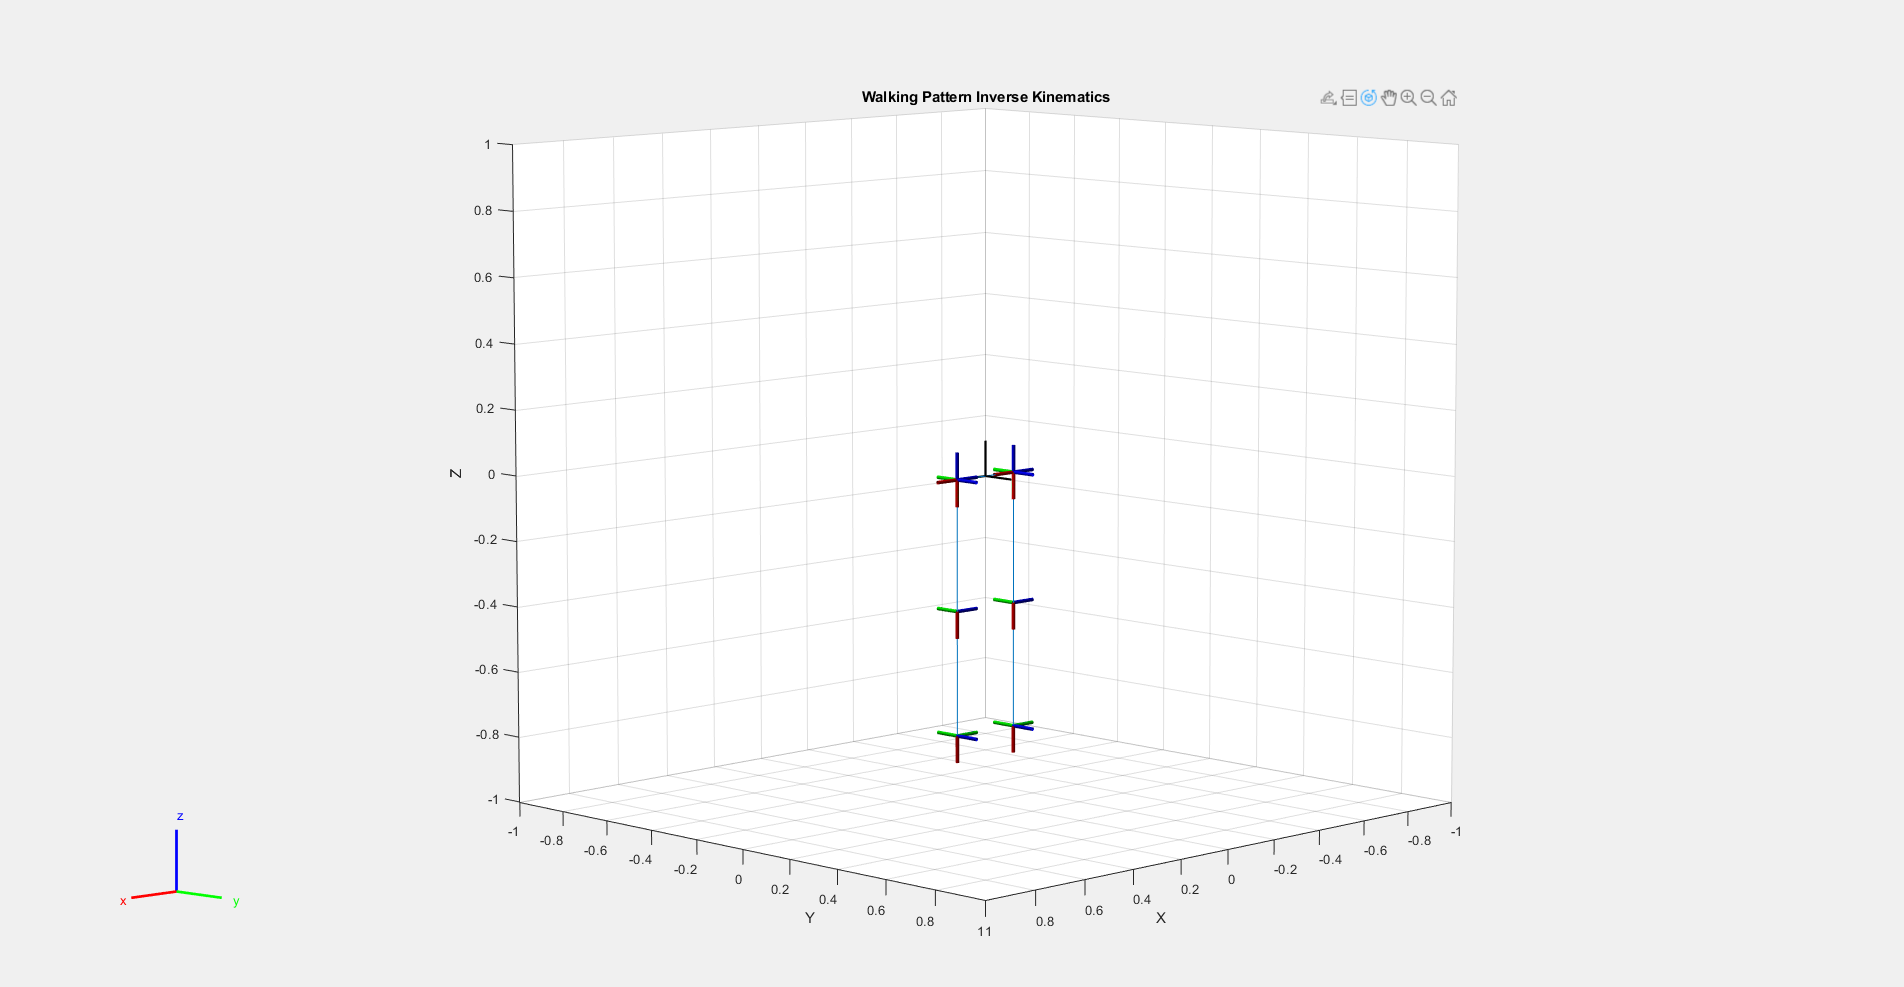

hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
desconfig = robot.homeConfiguration; 

qright0 = zeros(1,6); 
qleft0 = zeros(1,6); 
updateJoints(robot, qright0, qleft0)

## Animate Joint Trajectory

Note that feet orientation is always normal to the ground. Also note the Z vector of the end effector is pointed toward the ground. 

n = [0;  0; -1]; % x
s = [-1; 0; 0];  % y
a = [0;  1; 0];  % z
R = [n s a];   

for sIdx = 1:length(footinfos)
    % Extract X Y Z position states (indices 1, 3, and 5)
    stateL = footinfos{sIdx}.footleft([1 3 5],:); 
    stateR = footinfos{sIdx}.footright([1 3 5],:); 
    
    % Initialize matrices
    numIdx = size(stateL,2); 
    jointsLeft = zeros(6,numIdx); 
    jointsRight = zeros(6,numIdx); 
    transMatLeft = zeros(4,4,numIdx); 
    transMatRight = zeros(4,4,numIdx); 
    
    % Skip some intermediate steps when visualizing 
    for idx = 1:numIdx
        % Get Left joints
        p = stateL(:,idx); 
        transmat =  [R     p; 
                    [0 0 0 1]];
        isLeft = true; 
        qLeft = invKinBody2Foot(transmat, isLeft); % Call IK function
        jointsLeft(:,idx) = qLeft; 
        transMatLeft(:,:,idx) = transmat; 
        
        % Get Right joints
        p = stateR(:,idx); 
        transmat =  [R     p; 
                    [0 0 0 1]];
        isLeft = false; 
        qRight = invKinBody2Foot(transmat, isLeft);
        jointsRight(:,idx) = qRight; 
        transMatRight(:,:,idx) = transmat; 
        
        % Animate
        if animateOn
            if rem(idx,speedupfactor) == 0
                updateJoints(robot, qRight, qLeft);
            end 
        end
    end
    % save joints info 
    footinfos{sIdx}.jointsleft = jointsLeft; 
    footinfos{sIdx}.jointsright = jointsRight; 
    footinfos{sIdx}.transmatleft = transMatLeft; 
    footinfos{sIdx}.transmatright = transMatRight; 
end
% last update of Animation in case Animation is off 
updateJoints(robot, qRight, qLeft);

## Create Simulation Input (End Effector)

The two variables used inside the simulation are end effector position and orientation information for the left leg and the right leg. This end effector position and orientation information is in the form of 4-by-4 transformation matrices. 

timeVec = footinfos{1}.timevec; 
transMatLeft = footinfos{1}.transmatleft; 
transMatRight = footinfos{1}.transmatright; 
    
siminL.time = timeVec;
siminL.signals.values = transMatLeft;
siminL.signals.dimensions = [4,4];

siminR.time = timeVec;
siminR.signals.values = transMatRight;
siminR.signals.dimensions = [4,4];

for idx = 2:length(footinfos)
    timeVec = footinfos{idx}.timevec;

    transMatLeft = footinfos{idx}.transmatleft; 
    transMatRight = footinfos{idx}.transmatright; 

    siminL.time = [siminL.time timeVec];
    siminL.signals.values = cat(3,siminL.signals.values, transMatLeft);

    siminR.time = [siminR.time timeVec];
    siminR.signals.values = cat(3,siminR.signals.values, transMatRight);
end

## Helper Functions

function updateJoints(robot, anglesright, anglesleft)
    
    desconfig = robot.homeConfiguration;

    desconfig(1).JointPosition = pi; % angle offset 
    for idx = 1:length(anglesright)
        desconfig(idx+1).JointPosition = anglesright(idx);
    end 
    desconfig(2).JointPosition = desconfig(2).JointPosition - pi;
    desconfig(3).JointPosition = desconfig(3).JointPosition + pi/2; 
    
    desconfig(8).JointPosition = pi;
    for idx = 1:length(anglesleft)
        desconfig(idx+8).JointPosition = anglesleft(idx);
    end 
    desconfig(9).JointPosition = desconfig(9).JointPosition - pi; 
    desconfig(10).JointPosition = desconfig(10).JointPosition + pi/2; 
       
    % update graphics 
    show(robot, desconfig, 'PreservePlot', false);
    title('Walking Pattern Inverse Kinematics')
    pause(0.001)
end